# Actividad 1 (Velocidades Lineales y angulares)

**Daniel Castillo López A01737357**

- **Obtener** el vector de velocidades lineal y angular para la siguiente configuración:

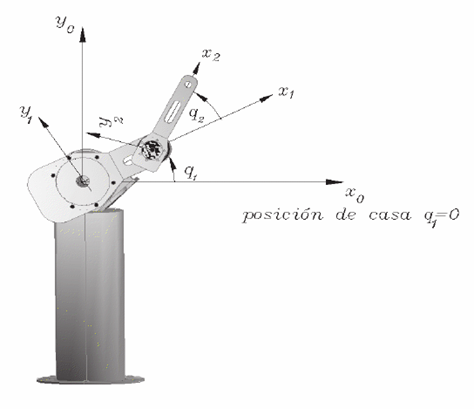

En esta sección definimos las coordenadas generalizadas y las velocidades con 2 grados de libertad, con dos juntas rotaciones.Primero, se limpian las variables del entorno y se definen variables simbólicas, incluyendo los ángulos de las juntas, junto a sus longitudes.Para iniciar con un vector que representará los angulos  y otro para de velocidades generalizadas , que es la derivada con respecto al tiempo de las coordenadas genralizadas, representando las velocidades angulares.

clear all
close all
clc
% declaración de variables simbolicas
syms th1(t) l1 t th2(t) l2

%Configuración del robt, 0 para junta rotacional, 1 para junta primática
RP=[0 0];
%cREAMOS EL VECTOR DE COORDENADAS GENERALIZADAS
Q= [th1 th2];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q); %simplificar la expreción matemática

(th1(t), th2(t))




%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t); %Utilizamos diff para derivadas cuya variable de referencia no depende de otra
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d          d        \
| -- th1(t), -- th2(t) |
\ dt         dt        /



Este código en MATLAB calcula la cinemática directa de un robot planar de 2 grados de libertad (GDL), con dos juntas rotacionales. Para después definir las matrices de rotación y vectores de traslación de cada articulación asi construyendo las matrices de transformación homogénea locales y globales, que permiten obtener la posición y la orientación de cada eslabón respecto al marco fijo. Al final extrae los vectores de posición y matrices de rotación de cada eslabón mostrando los resultados

%Número de grados de libertad del robot
GDL= size(RP,2);%El dos indica la dimensión de las columnas
GDL_str= num2str(GDL);%Convertimos el valor numerico a una cadena de carácter tipo string

%Articulación 1
%Vector de translación de la articulación 1 respecto a 0
P(:,:,1)=[l1*cos(th1);
          l1*sin(th1);
                    0];

%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)=[cos(th1) -sin(th1) 0; %Analisis del robot del péndulo 
          sin(th1)  cos(th1) 0;
          0         0        1];

%Vector de translación de la articulación 1 respecto a 0
P(:,:,2)=[l2*cos(th2);
          l2*sin(th2);
                    0];

%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)=[cos(th2) -sin(th2) 0; 
          sin(th2)  cos(th2) 0;
          0         0        1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1,3);

%Inicializamos las matrices de transformación Homogénea locales
%Rotación, Traslación y vector de ceros y el 1
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
%Rotación, Traslación y vector de ceros y el 1
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos los vectores de posición vistos desde el marco de referencia
%inercial
PO(:,:,GDL)= P(:,:,GDL);

%Inicializamos los vectores de posición vistos desde el marco de referencia
%inercial
RO(:,:,GDL)= R(:,:,GDL);

for i=1:GDL
    i_str= num2str(i);
    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty  (A(:,:,i));

    %Globales
    try %Siempre multiplicara 
        T(:,:,i)= T(:,:,i-1)*A(:,:,i);%(Sobre la posición anterior)
    catch
        T(:,:,i)= A(:,:,i);%Caso especifico cuano i=1
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i));

    %Obtenemos la matriz RO y el vector de tralación PO de la matriz de
    %transformación Homogénea global T(:,:,GDL)
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)=T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));

    %%Hasta aqui cinematica directa%%
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2


/ #2, -#1, 0, l1 cos(th1(t)) + l2 #2 \
|                                    |
| #1,  #2, 0, l1 sin(th1(t)) + l2 #1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




/ cos(th1(t) + th2(t)), -sin(th1(t) + th2(t)), 0 \
|                                                |
| sin(th1(t) + th2(t)),  cos(th1(t) + th2(t)), 0 |
|                                                |
\           0,                    0,           1 /



/ l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                          |
| l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                          |
\                     0                    /



disp('Jacobian lineal obtenido de forma diferencial');

Jacobian lineal obtenido de forma diferencial


 Ahora se calcula el jacobiano de posición lineal del extremo del péndulo con respecto a las coordenadas generalizadas. Obtenermos las derivadas parciales de las componentes x,y,zx, y, z de la posición final del extremo en respecto a cada ángulo. Luego, construye la matriz jacobiana que se relaciona las velocidades articulares con la velocidad lineal del extremo.

%Derivadas parciales de x respecto a th1
Jv11= functionalDerivative(P(1,1,GDL),th1);
Jv12= functionalDerivative(P(1,1,GDL),th2);

%Derivadas parciales de y respecto a th1
Jv21= functionalDerivative(P(2,1,GDL),th1);
Jv22 = functionalDerivative(PO(2,1,GDL), th2);
%Derivadas parciales de z respecto a th1
Jv31= functionalDerivative(P(3,1,GDL),th1);
Jv32 = functionalDerivative(PO(3,1,GDL), th2);

%Obtenemos la cinemática deiferencial del péndulo a partir de la cinemática
%directa
jv_d=simplify([Jv11 Jv12; ...
               Jv21 Jv22 ; ...
               Jv31 Jv32]);

pretty(jv_d)

/ 0,     -l2 sin(th2(t))     \
|                            |
| 0, l2 cos(th1(t) + th2(t)) |
|                            |
\ 0,            0            /



Al calcula el jacobiano lineal y angular en una forma analítica, consideramos el tipo de articulación rotacional o prismática. Primero las matrices del jacobiano lineal y angular�, después recorre cada articulación para determinar la contribución de cada una. Si es rotacional, se calcula como el producto cruz entre el eje de rotación y el vector posición. Si es prismática se establece la dirección del eje.

%Calculamos el jacobiano lineal y angular de forma analítica
%Inicializamos jacobiano analíticos (lineal y angular)
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);

for k=1:GDL
    if(RP(k)==0)%Casos: articulaciones rotacional y primática

        %Para las articulaciones rotacionales
        try
            Jv_a(:,k)= cross(RO(:,:,k-1),PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1],PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz
            Jw_a(:,k)= [0,0,1];%Si no hay matriz de rotación previa se obtiene la matriz de identidad
        end
    elseif (RP(k)==1)%Casos: articulación rotacional y prismaática
        %para articulaciones prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
            Jw_a(:,k)=[0,0,0];
    end
end

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);

Utilizamos los jacobinaos analicos lineas y angular que habiamos hecho para determinar las velocidades lineales y angulares del extremo  del objeto.

disp('Jacobiano lineal obtenido de forma analitica');

Jacobiano lineal obtenido de forma analitica


pretty (Jv_a);

/ #2, #2 \
|        |
| #1, #1 |
|        |
\  0,  0 /

where

   #1 == l1 cos(th1(t)) + l2 cos(th1(t) + th2(t))

   #2 == - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t))




disp('Jacobiano angularl obtenido de forma analitica');

Jacobiano angularl obtenido de forma analitica


pretty (Jw_a);

/ 0, 0 \
|      |
| 0, 0 |
|      |
\ 1, 1 /




disp('Velocidad lineal obtenida mediante  el Jacobiano lineal');

Velocidad lineal obtenida mediante  el Jacobiano lineal


V = simplify(Jv_a*Qp');
pretty(V);

/   / _________   _________ \                                            \
|   |  d           d        |                                            |
| - | -- th1(t) + -- th2(t) | (l1 sin(th1(t)) + l2 sin(th1(t) + th2(t))) |
|   \ dt          dt        /                                            |
|                                                                        |
|  / _________   _________ \                                             |
|  |  d           d        |                                             |
|  | -- th1(t) + -- th2(t) | (l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)))  |
|  \ dt          dt        /                                             |
|                                                                        |
\                                    0                                   /



disp('Velocidad angular obtenida mediante  el Jacobiano angular');

Velocidad angular obtenida mediante  el Jacobiano angular


W = simplify(Jw_a*Qp');
pretty(W);

/           0           \
|                       |
|           0           |
|                       |
| _________   _________ |
|  d           d        |
| -- th1(t) + -- th2(t) |
\ dt          dt        /

